# **Inspection Performance Analysis (CoDPAD M2)**

CoDPAD module 1-2 : Vehicle performance analysis - Basic vehicle characteristics analysis

본 장에서는 앞서 산출된 '기체제어성능'을 바탕으로 기체의 '검사성능'을 대표할 수 있는 지표를 산출한다. 검사성능은 김발의 자세 및 지향 안정성에서 출발하여 상태유지비행(steady state flight) 시의 지향정밀도(Pointing Accuracy)와 화각누락률(FOV omit prob.)까지 포함한다. 

[https://nearth.atlassian.net/l/c/jsFMKKDf](https://nearth.atlassian.net/l/c/jsFMKKDf)

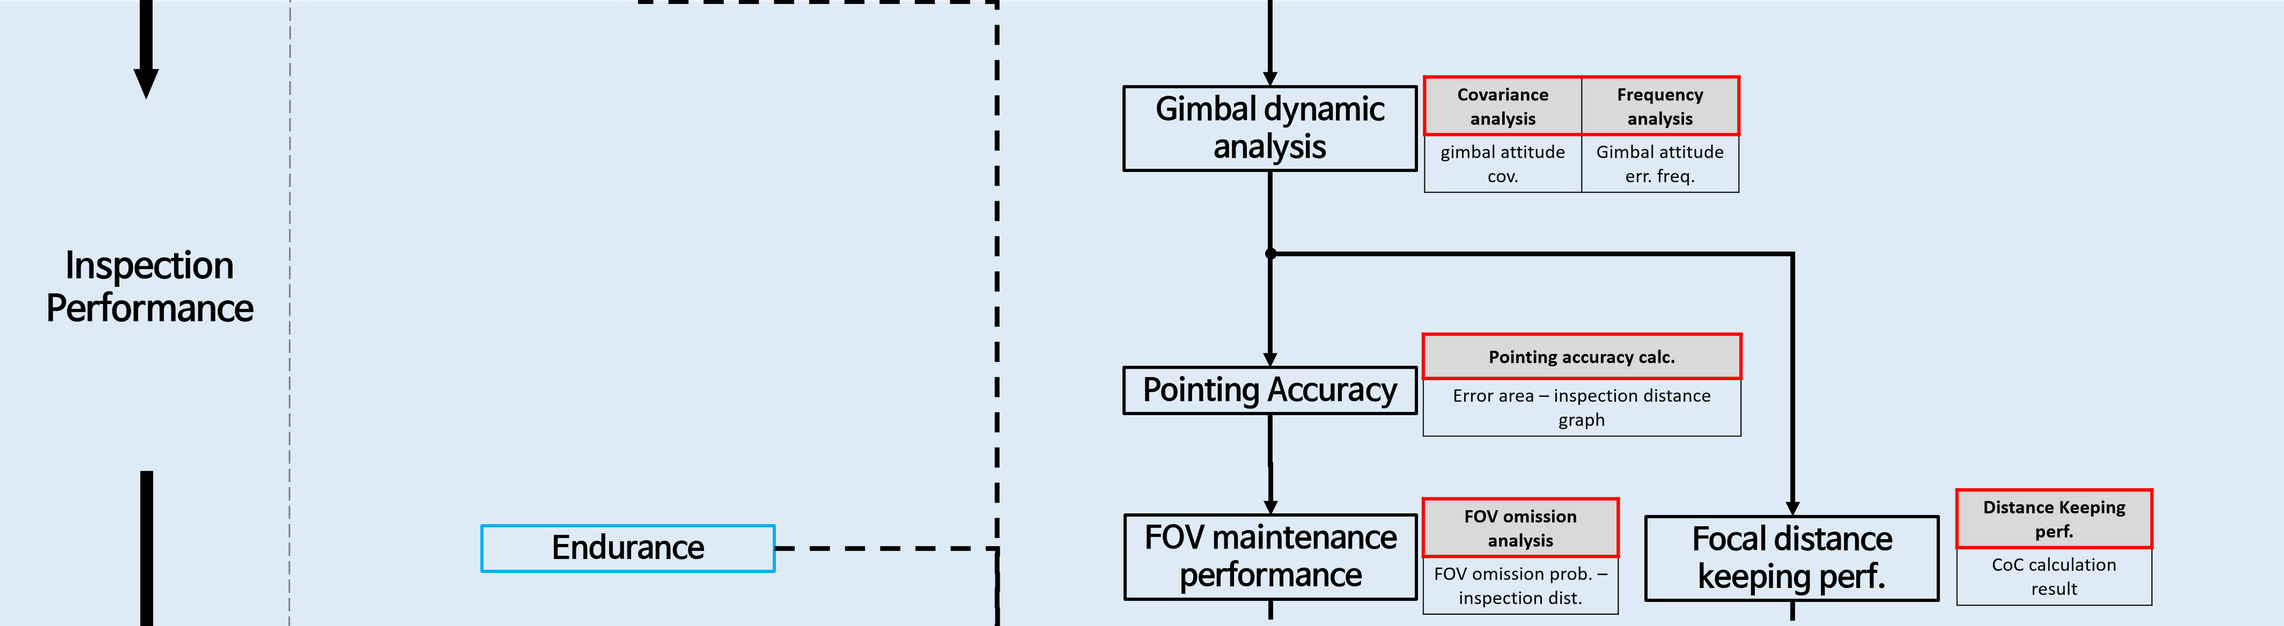

cd(fileparts(matlab.desktop.editor.getActiveFilename))
d2r = pi/180;
global calcDensity

## **User Input**

**index guide**

1 : roll rate (p)

2 : pitch rate (q)

3 : yaw rate (r)

4 : Roll angle ($\phi$)

5 : Pitch angle ($\theta$)

6 : Yaw angle ($\psi$)

7 : u

8 : v

9 : w

10: X

11: Y

12: Z

13: gimbal Roll

14: gimbal Pitch

15: gimbal Yaw

isGimbalVehicle = includeSweep;
if isGimbalVehicle
    gvResult = load("gvResult.mat");
    gvResult = gvResult.gvResult;
end
covResult = load("covResult.mat")

covResult = struct with fields:
    covResult: [1×1 struct]


covResult = covResult.covResult;
sampleVariable = load("sampleVariable.mat")

sampleVariable = struct with fields:
    sampleVariable: [1×1 struct]


sampleVariable = sampleVariable.sampleVariable;
inspectionDistance = 10

inspectionDistance = 10

confidence = 0.9

confidence = 0.9000

calcDensity = 300

calcDensity = 300

lensF = 2.8

lensF = 2.8000

lensName = "Nikon Z7"

lensName = "Nikon Z7"

CoCLimit = 0.025

CoCLimit = 0.0250

fovHor = 4.2

fovHor = 4.2000

fovVer = 3.3

fovVer = 3.3000

## APPENDIX

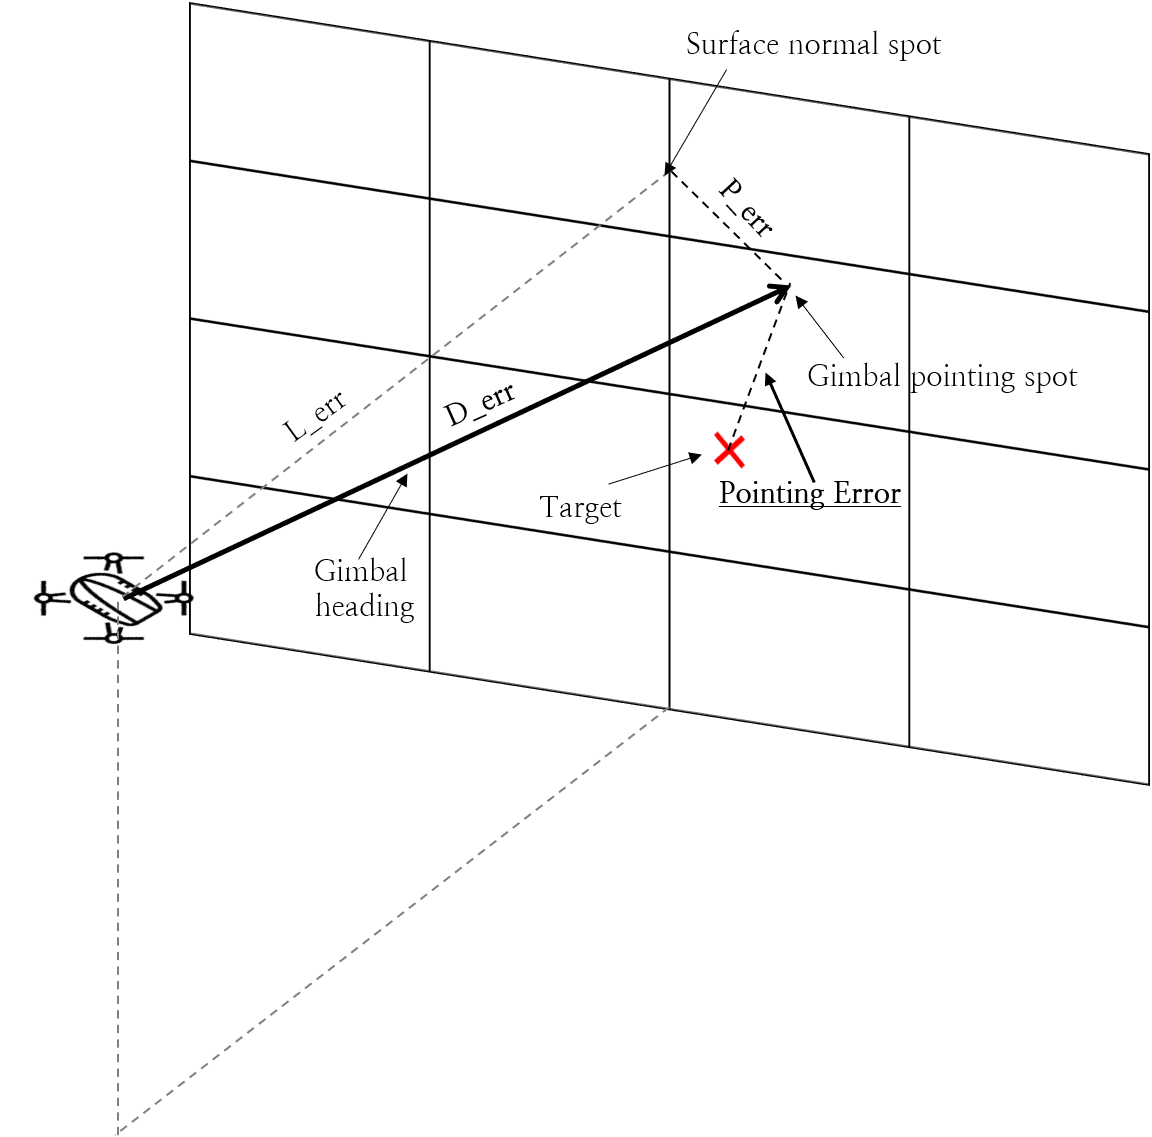

## Gimbal Holding Performance

This part suggests the gimbal's basic dynamic characteristics and analyzes the gimbal attitude error characteristics occuring during steady-state flight situation. Also, the interference characteristic between the vehicle and the payload is also suggested using transfer function estimation algorithm.

### Basic dynamic characteristic

Futurework

#### Step response

#### Frequency response

Futurework

Bandwidth

GM - PM

### Gimbal - Vehicle interference

The results shown in this part is acquired from Roll sweep test (test idx. #10). The transfer function from vehicle Roll command to gimbal attitude angle is estimated, and then analyzed using bode plot. This allows the user to identify peak amplitudes and frequencies.

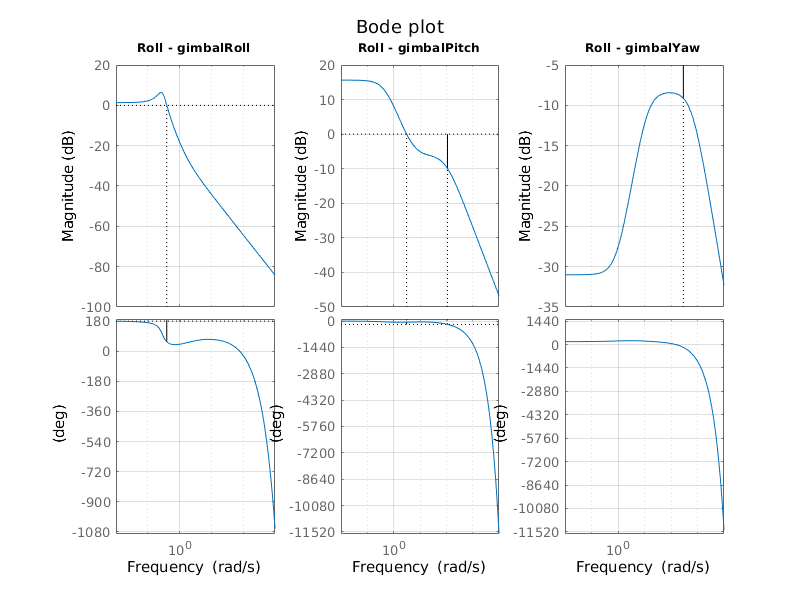

dataName = {'Roll - gimbalRoll','Roll - gimbalPitch','Roll - gimbalYaw'};
gvTableResult = [];
figure(1)
clf
set(gcf,'Position',[10 10 800 600])
for i = 1:3
    gvSys = tf(gvResult{i}.Num,gvResult{i}.Den,'ioDelay',gvResult{1}.Delay); 
    subplot(1,3,i)
    margin(gvSys)
    hold on
    grid on
    title(dataName{i},'fontsize',14)
    ylabel('');
    [gpeak, fpeak] = getPeakGain(gvSys);
    gvTableResult(i,:) = [gpeak, fpeak/2/pi];
end
sgtitle('Bode plot')

columns = {'Peak gain [dB]', 'Peak frequency [hz]'};
rows = dataName;
T = table(gvTableResult(:,1),gvTableResult(:,2),'Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
                          Peak gain [dB]    Peak frequency [hz]
                          ______________    ___________________

    Roll - gimbalRoll         2.0887             0.041864      
    Roll - gimbalPitch        6.0424                    0      
    Roll - gimbalYaw         0.37837               14.082      


### Gimbal attitude error distribution 

Standard deviation of gimbal attitude error is provided in this section. Also, gimbalYaw-gimbalPitch angle's binomial distribution, which contributes to pointing accuracy, is shown below.

Std deviation

columns = {'posHold','velHold'};
rows = {'gimbal Roll [deg]','gimbal Pitch [deg]','gimbal Yaw [deg]'};
T = table(covResult.posHoldStd(13:15)',covResult.velHoldStd(13:15)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
                          posHold     velHold 
                          ________    ________

    gimbal Roll [deg]     0.059678    0.058693
    gimbal Pitch [deg]    0.057676     0.23501
    gimbal Yaw [deg]      0.057849    0.061593


Covariance matrix

covResult.pos(13:15,13:15)

ans =     0.0036   -0.0001   -0.0001
   -0.0001    0.0033    0.0001
   -0.0001    0.0001    0.0033


covResult.vel(13:15,13:15)

ans =     0.0034    0.0001    0.0001
    0.0001    0.0552    0.0042
    0.0001    0.0042    0.0038


## Pointing Accuracy

Pointing accuracy represents the ability for a vehicle to accurately aim specific target of interest. Various state data are merged in this process.

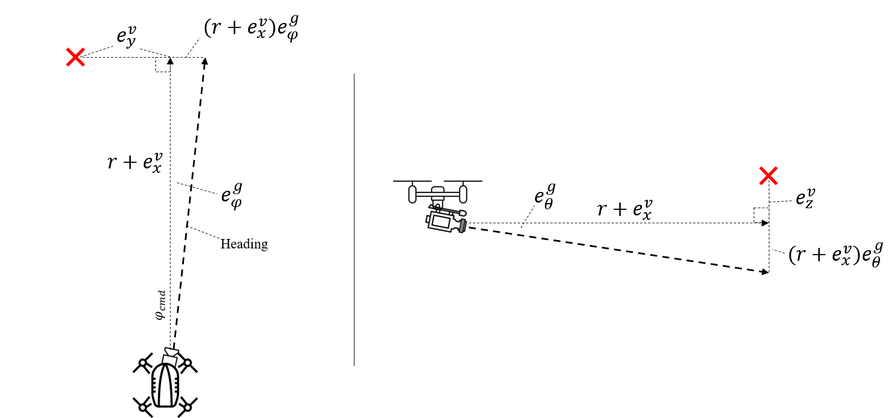


$$l_{err} = (r+e_{x}^v+SSE_x)$$



$$Pointing_{err} = \sqrt{\{l_{err}tan(e_\psi^g+SSE_\psi^g)+e_y^v+SSE_y\}^{2}+\{l_{err}tan(e_\theta^g+SSE_\theta^g)+e_{z}^v+SSE_z\}^{2}}$$


#### Pointing error distribution

% Pointing Accuracy calculation
yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;

yawG_err_v = sampleVariable.vel(:,15) * d2r;
pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
yawG_sse_v = covResult.velHoldStd(15) * d2r;
pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14

X_err_v = sampleVariable.vel(:,10);
Y_err_v = sampleVariable.vel(:,10); %%TODO 11
Z_err_v = sampleVariable.vel(:,12);

l_err_v =  inspectionDistance + X_err_v;
Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;

% Multivariate Analysis
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(Perr_x_p,Perr_y_p,confidence);
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(Perr_x_v,Perr_y_v,confidence);
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);

90% posHold confidence area is 0.13428 [deg^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);

90% velHold confidence area is 1.6054 [deg^2]


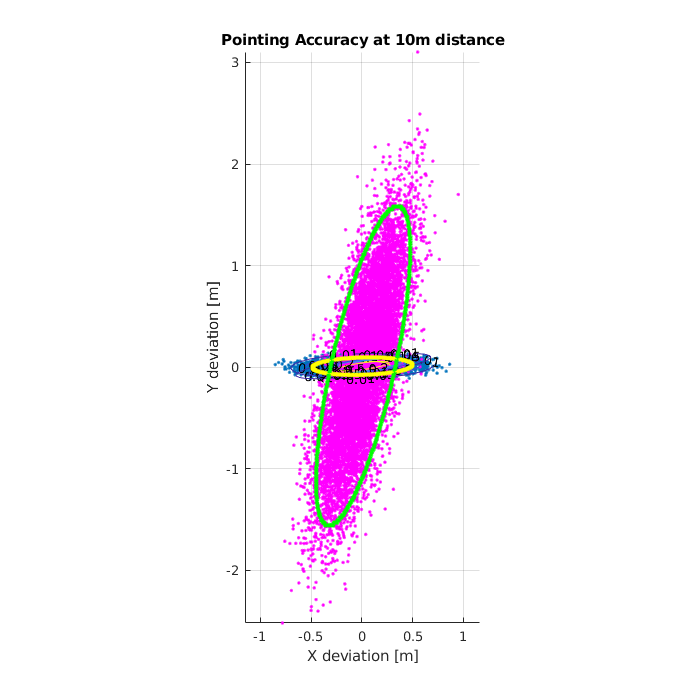

posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(2)
clf
hold on
% plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
% plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');
plot(Perr_x_p,Perr_y_p,'.')
plot(Perr_x_v,Perr_y_v,'m.')

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
contour(vel_X,pos_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
titleText = ['Pointing Accuracy at ', num2str(inspectionDistance), 'm distance'];
title(titleText);
xlabel('X deviation [m]')
ylabel('Y deviation [m]')
set(gcf,'Position',[10 10 700 700])

#### Pointing accuracy - range graph

## Pointing stability

Pointing stability is used to evaluate whether the system can provide sufficient stability during inspection. Its value is basically the derivative of pointing accuracy. The less pointing stability means more probability of acquiring blurred image.


$$l_{err} = (r+e_{x}^v+SSE_x)$$



$$Pointing_{err} = \sqrt{\{l_{err}tan(e_\psi^g+SSE_\psi^g)+e_y^v+SSE_y\}^{2}+\{l_{err}tan(e_\theta^g+SSE_\theta^g)+e_{z}^v+SSE_z\}^{2}}$$


#### Shaking rate distribution

% Futurework

% % Shake rate calculation
% yawG_err_p = sampleVariable.pos(:,15) * d2r;
% pitchG_err_p = sampleVariable.pos(:,14) * d2r;
% yawG_sse_p = covResult.posHoldStd(15) * d2r;
% pitchG_sse_p = covResult.posHoldStd(14) * d2r;
% 
% X_err_p = sampleVariable.pos(:,10);
% Y_err_p = sampleVariable.pos(:,10); %%TODO 11
% Z_err_p = sampleVariable.pos(:,12);
% 
% l_err_p =  inspectionDistance + X_err_p;
% Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
% Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;
% 
% yawG_err_v = sampleVariable.vel(:,15) * d2r;
% pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
% yawG_sse_v = covResult.velHoldStd(15) * d2r;
% pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14
% 
% X_err_v = sampleVariable.vel(:,10);
% Y_err_v = sampleVariable.vel(:,10); %%TODO 11
% Z_err_v = sampleVariable.vel(:,12);
% 
% l_err_v =  inspectionDistance + X_err_v;
% Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
% Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;
% 
% % Multivariate Analysis
% [pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(Perr_x_p,Perr_y_p,confidence);
% [vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(Perr_x_v,Perr_y_v,confidence);
% A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
% disp(A);
% A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
% disp(A);
% posEdgeIdx = convhull(pos_peripheral);
% velEdgeIdx = convhull(vel_peripheral);
% 
% figure(3)
% clf
% hold on
% % plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
% % plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');
% plot(Perr_x_p,Perr_y_p,'.')
% plot(Perr_x_v,Perr_y_v,'m.')
% 
% contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
% contour(vel_X,pos_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
% grid on
% plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
% plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
% plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
% plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
% axis equal
% titleText = ['Pointing Accuracy at ', num2str(inspectionDistance), 'm distance'];
% title(titleText);
% xlabel('X deviation [m]')
% ylabel('Y deviation [m]')
% set(gcf,'Position',[10 10 700 700])

#### Shaking rate - range graph

Futurework

## Focal Point Maintenance Performance

Sometimes, inspection device require the vehicle to maintain specific inspection distance during inspection process. For visual inspection, maintiaining the distance directly relates to clarity of an image as the focal distance of a camera is fixed. This part suggests distance maintenance performance during cruising (non zero v velocity) situation. Clarity of an image is quantitatively evaluated using a indicator called 'CoC (Circle of Confusion)'

[Circle of Confusion - Wikipedia](https://en.wikipedia.org/wiki/Circle_of_confusion)

#### Focal point maintenance performance

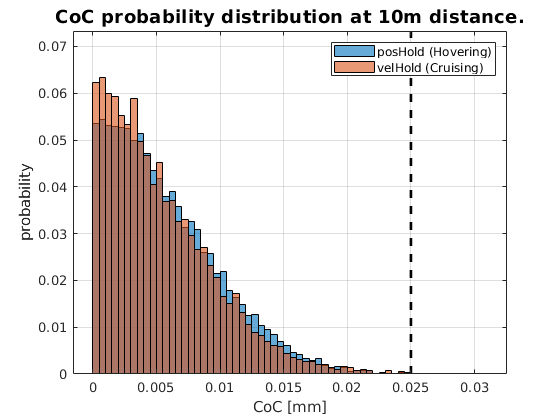

% Inspection distance calc.
yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;
Perr_tot_p = sqrt(Perr_x_p.^2 + Perr_y_p.^2);
Derr_p = sqrt(Perr_tot_p.^2 + l_err_p.^2);

CoC_p = abs(Derr_p - inspectionDistance)./Derr_p .* lensF^2 ./ 3.5 ./ (inspectionDistance - lensF);

yawG_err_v = sampleVariable.vel(:,15) * d2r;
pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
yawG_sse_v = covResult.velHoldStd(15) * d2r;
pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14

X_err_v = sampleVariable.vel(:,10);
Y_err_v = sampleVariable.vel(:,10); %%TODO 11
Z_err_v = sampleVariable.vel(:,12);

l_err_v =  inspectionDistance + X_err_v;
Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;
Perr_tot_v = sqrt(Perr_x_v.^2 + Perr_y_v.^2);
Derr_v = sqrt(Perr_tot_v.^2 + l_err_v.^2);

CoC_v = abs(Derr_v - inspectionDistance)./Derr_v .* lensF^2 ./ 3.5 ./ (inspectionDistance - lensF);

% CoC probability distribution
figure(4)
clf
h1 = histogram(CoC_p);
hold on
h2 = histogram(CoC_v);
h1.Normalization = 'probability';
h2.Normalization = 'probability';

maxY = max(max(h1.Values),max(h2.Values))+0.01;
plot([CoCLimit CoCLimit],[0 maxY],'k--','LineWidth',2)
titleText = ['CoC probability distribution at ', num2str(inspectionDistance),'m distance.'];
title(titleText,'FontSize',14);
grid on
ylim([0 maxY])
xlabel('CoC [mm]')
ylabel('probability')
legend('posHold (Hovering)', 'velHold (Cruising)')

% CoC threshold violation probability.
pos_coc_dist = fitdist(CoC_p,'halfNormal');
vel_coc_dist = fitdist(CoC_v,'halfNormal');

pos_coc_vio = cdf(pos_coc_dist, CoCLimit) * 100;
vel_coc_vio = cdf(vel_coc_dist, CoCLimit) * 100;

dispTextA = ['CoC satisfaction probability (posHold) : ',num2str(pos_coc_vio),'%'];
dispTextB = ['CoC satisfaction probability (velHold) : ',num2str(vel_coc_vio),'%'];

disp(dispTextA);

CoC satisfaction probability (posHold) : 99.9489%


disp(dispTextB);

CoC satisfaction probability (velHold) : 99.9745%


#### CoC satisfaction probability - range graph

## FOV Omission Probability

With FOVs specified, it is possible to calculate the probability of omitting a certain pixel. By calculating this probability along the pixels within the FOV, FOV omitssion probability map can be generated as shown below. This result can be used in determining overlap ratio between the shots.


$$P(\vec{x} omit)  = 1 - P( | \vec{x}-\vec{e}(\mu,\sigma)| \preceq {\vec{X}\over 2})$$


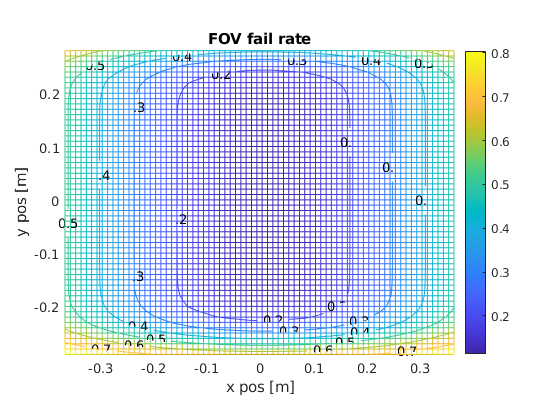

covSampleNum = size(sampleVariable.pos,1);

yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;

FovXrad = fovHor * d2r;
FovYrad = fovVer * d2r;
viewX = tan(FovXrad/2) * inspectionDistance;
viewY = tan(FovYrad/2) * inspectionDistance;

[X,Y] = meshgrid(-viewX:0.01:viewX,-viewY:0.01:viewY);
out = zeros(size(X));
for i = 1:size(X,1)
for j= 1:size(X,2)
px = length(find(abs(Perr_x_p-X(i,j))<viewX))/covSampleNum;
py = length(find(abs(Perr_y_p-Y(i,j))<viewY))/covSampleNum;
out(i,j) = 1-px*py;
end
end
figure(5)
clf
mesh(X,Y,out)
hold on
contour3(X,Y,out,'ShowText','on')
title('FOV fail rate')
xlabel('x pos [m]')
ylabel('y pos [m]')
colorbar
axis equal
view([-0 90])

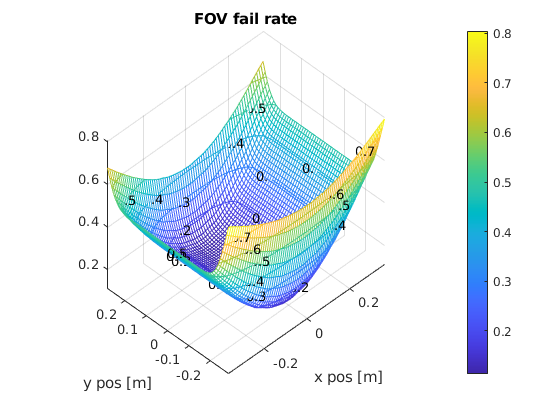

figure(6)
clf
mesh(X,Y,out)
hold on
contour3(X,Y,out,'ShowText','on')
title('FOV fail rate')
xlabel('x pos [m]')
ylabel('y pos [m]')
colorbar
axis equal
view([-45 45])


% omission probability
omitNum = size(find(out>1-confidence),1);
totNum = size(out,1) * size(out,2);
omitRatio = omitNum/totNum;
SatisRatio = 1-omitRatio;
dispText = [num2str(confidence*100),'% confidence FOV acquisition ratio : ',num2str(SatisRatio * 100),'%'];
disp(dispText);

90% confidence FOV acquisition ratio : 0%


#### FOV omission probability - range graph

## Function definition

function [confidence_area,out,maxPdf,peripheral,X,Y] = multiVariateAnalysis(x_data,y_data,confidence)
% Internal parameters : DO NOT TOUCH
global calcDensity
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = calcDensity;

% calculate maxpdf
mu_x = mean(x_data);
mu_y = mean(y_data);
std_x = std(x_data);
std_y = std(y_data);
covar = cov([x_data,y_data]);

maxPdf = mvnpdf([mu_x mu_y],[mu_x mu_y],covar);
thres = level * maxPdf;

% distribution data for plotting
[X,Y] = meshgrid(linspace(mu_x-std_x*zRange,mu_x+std_x*zRange,50),linspace(mu_y-std_y*zRange,mu_y+std_y*zRange,50));
out = BiNorm(X,Y,[mu_x;mu_y],covar);

% distribution data for prob. calc.
xGrid = linspace(mu_x-zRange*std_x,mu_x+zRange*std_x,density);
yGrid = linspace(mu_y-zRange*std_y,mu_y+zRange*std_y,density);
xGrid(end) = [];
yGrid(end) = [];
xGridSize = xGrid(2)-xGrid(1);
yGridSize = yGrid(2)-yGrid(1);
gridArea = xGridSize * yGridSize;

for i = xGrid
    for j = yGrid
        if mvnpdf([i j],[mu_x mu_y],covar) >= thres
            cumulated = cumulated + mvncdf([i j],[i+xGridSize j+yGridSize],[mu_x mu_y],covar);
            index = vertcat(index,[i,j]);
        end
    end
end

% cumulated % for verification. This value must be equal to 'confidence' param.

for i = 1:length(index)
    if boxed(i,index,xGridSize,yGridSize)
        peripheral = vertcat(peripheral,index(i,:));
    end
end

confidence_area = length(index) * gridArea;
end

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end